# A Data Driven Statistical Model for Glass Identification Given Chemical Composition

## A Comparision between Naive Bayes and Random Forests

**Ayliah Fani - 200044837**

## 1. Data Selection

% Data comes from: https://archive.ics.uci.edu/ml/datasets/glass+identification
glass_data_import = readtable("glass.data.csv");

## **2. Data Preparation**

### **A. Cleaning**

% remove id column & reindex
glass = glass_data_import(:,2:end);

% rename columns
glass.Properties.VariableNames = {'refractive_index' 'Na' 'Mg' 'Al' 'Si' 'K' 'Ca' 'Ba' 'Fe' 'type_of_glass'};

% check for missing values
missingvalues = sum(ismissing(glass))

missingvalues =      0     0     0     0     0     0     0     0     0     0



% split predictors and response
X = glass{:,1:end-1};
Y = glass{:,end};

% look at response
tabulate(glass.type_of_glass)

  Value    Count   Percent
      1       70     32.71%
      2       76     35.51%
      3       17      7.94%
      4        0      0.00%
      5       13      6.07%
      6        9      4.21%
      7       29     13.55%


There is quite a bit of class imbalance that needs to be taken into consideration.

### **B. Descriptive Statistics**

% statistical summary of each variable
format compact
summary(glass);

Variables:
    refractive_index: 214×1 double
        Values:
            Min        1.5111 
            Median     1.5177 
            Max        1.5339 
    Na: 214×1 double
        Values:
            Min        10.73  
            Median      13.3  
            Max        17.38  
    Mg: 214×1 double
        Values:
            Min            0  
            Median      3.48  
            Max         4.49  
    Al: 214×1 double
        Values:
            Min         0.29  
            Median      1.36  
            Max          3.5  
    Si: 214×1 double
        Values:
            Min        69.81  
            Median     72.79  
            Max        75.41  
    K: 214×1 double
        Values:
            Min            0  
            Median     0.555  
            Max         6.21  
    Ca: 214×1 double
        Values:
            Min         5.43  
         

### **C. Visualisation**

allX = [glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass];
allY = [glass.refractive_index, glass.Na, glass.Mg, glass.Al, glass.Si, glass.K, glass.Ca, glass.Ba, glass.Fe];
titles = glass.Properties.VariableNames;

% % scatter plots of refractive index and glass oxide contents of each glass type
% for k=1:size(allX,2)
%     figure(k)
%     scatter(allX(:,k),allY(:,k))
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end
% 
% % box plots of refractive index and glass oxide content for each glass type
% for k=1:size(allX,2)
%     figure(k)
%     boxplot(allY(:,k),glass.type_of_glass)
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end

from the box plots I might look into removing outliers since some ML techniques are sensitive to them.

### **D. Partitioning the Data**

% [m,n] = size(glass) ; 
% idx = randperm(m) ;  % shuffle the rows 
% 
% %training data
% train = glass(idx(1:round(m*0.70)),:)  ;
% train_X = train(:,1:end-1);
% train_Y = train(:,end);
% 
% %testing data
% test = glass(idx(round(m*0.70)+1:round(m*0.85)),:) ;
% 
% % validation data
% validate = glass(idx(round(m*0.85)+1:end),:) ;


rng(10,'twister')           % For reproducibility
part = cvpartition(Y,'Holdout',0.3);

% training data
istrain = training(part);   % Data for fitting
train_X = X(istrain,:);
train_Y = Y(istrain);

% testing data
istest = test(part);        % Data for quality assessment
test_X = X(istest,:);
test_Y = Y(istest);

% look at count of classes present in the training set
tabulate(train_Y)

  Value    Count   Percent
      1       48     32.00%
      2       54     36.00%
      3       12      8.00%
      4        0      0.00%
      5        9      6.00%
      6        7      4.67%
      7       20     13.33%


## **3. Model Selection**

### **A. Naïve Bayes**

Since variance is 0 for many predictors in the samples, Naïve Bayes cannot be used.

### B. Random Forests

#### i. Fitting a Model

Several classes are quite a low percentage of the data. This imbalance indicates that `RUSBoost` is an appropriate algorithm to use since the data is multiclass and skewed, but it is not in the scope of this course so `Bag` will be used.

N = sum(istrain);         % Number of observations in the training sample
t = templateTree('MaxNumSplits',N);
rf_mdl = fitcensemble(train_X,train_Y,'Method','RUSBoost', ...
    'NumLearningCycles',200,'Learners',t,'LearnRate',0.1);

#### ii. Cross Validation

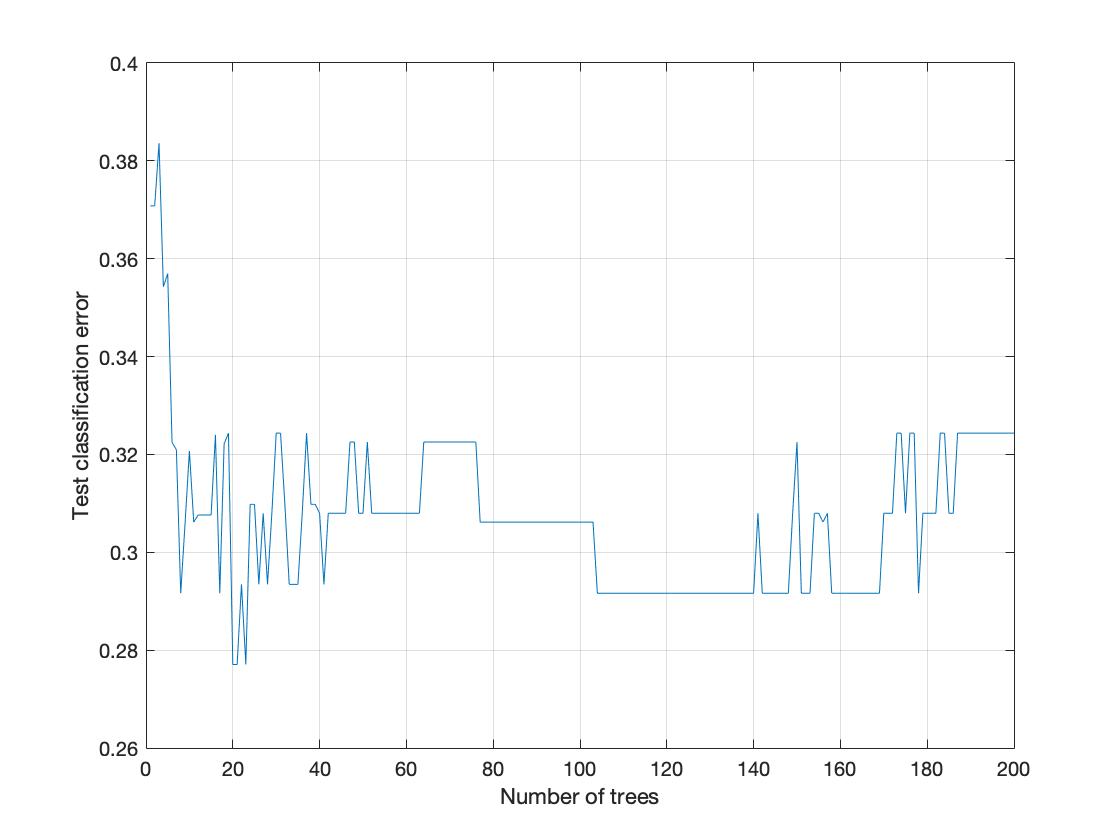

% Plot misclassification/loss against the number of trees in the ensemble.
figure;
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'));
grid on;
xlabel('Number of trees');
ylabel('Test classification error');

The ensemble reaches the minimum error between 130-134 trees with an error of ~26%

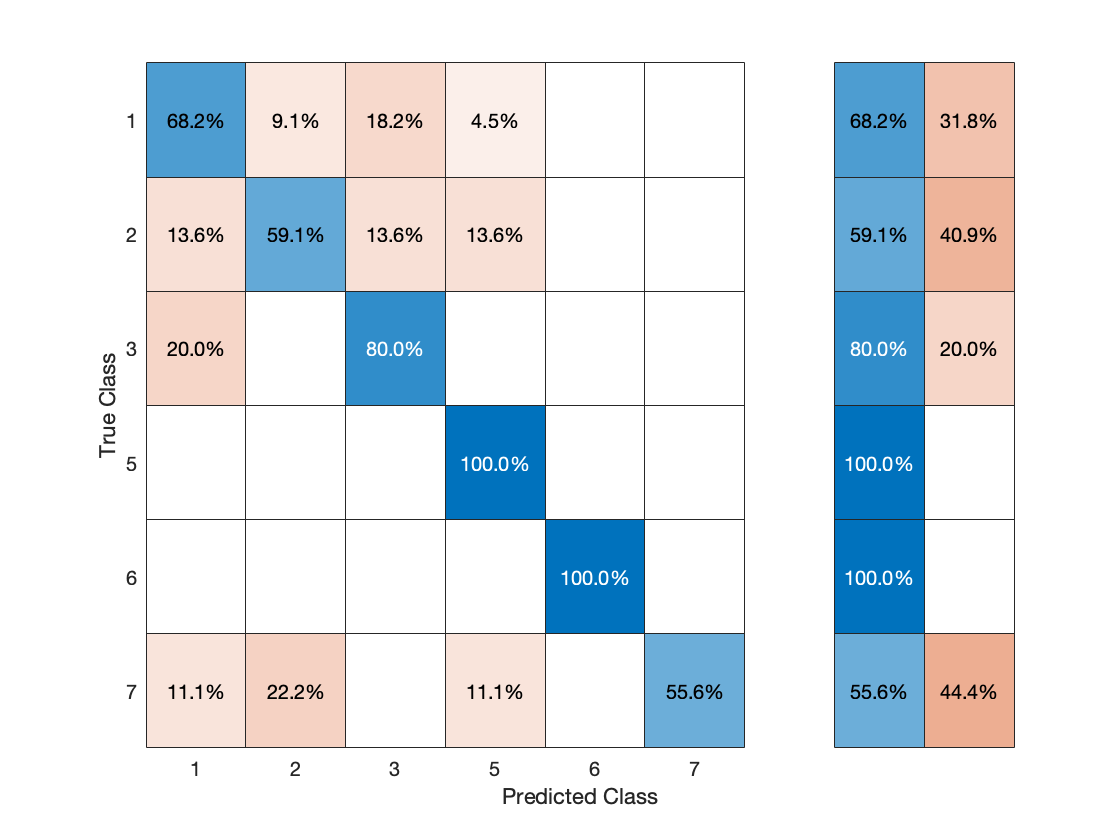

% confusion matrix
Yfit = predict(rf_mdl, test_X);
confusionchart(test_Y,Yfit,'Normalization','row-normalized','RowSummary','row-normalized')


% loss
rf_loss = loss(rf_mdl, test_X, test_Y)

rf_loss = 0.3244

Generate a five-fold cross-validated ensemble.

% cross validation
rf_cv = fitcensemble(X,Y,'Method','RUSBoost', ...
    'NumLearningCycles',200,'Learners',t,'LearnRate',0.1,'Kfold',5);

Examine the cross-validation loss as a function of the number of trees in the ensemble.

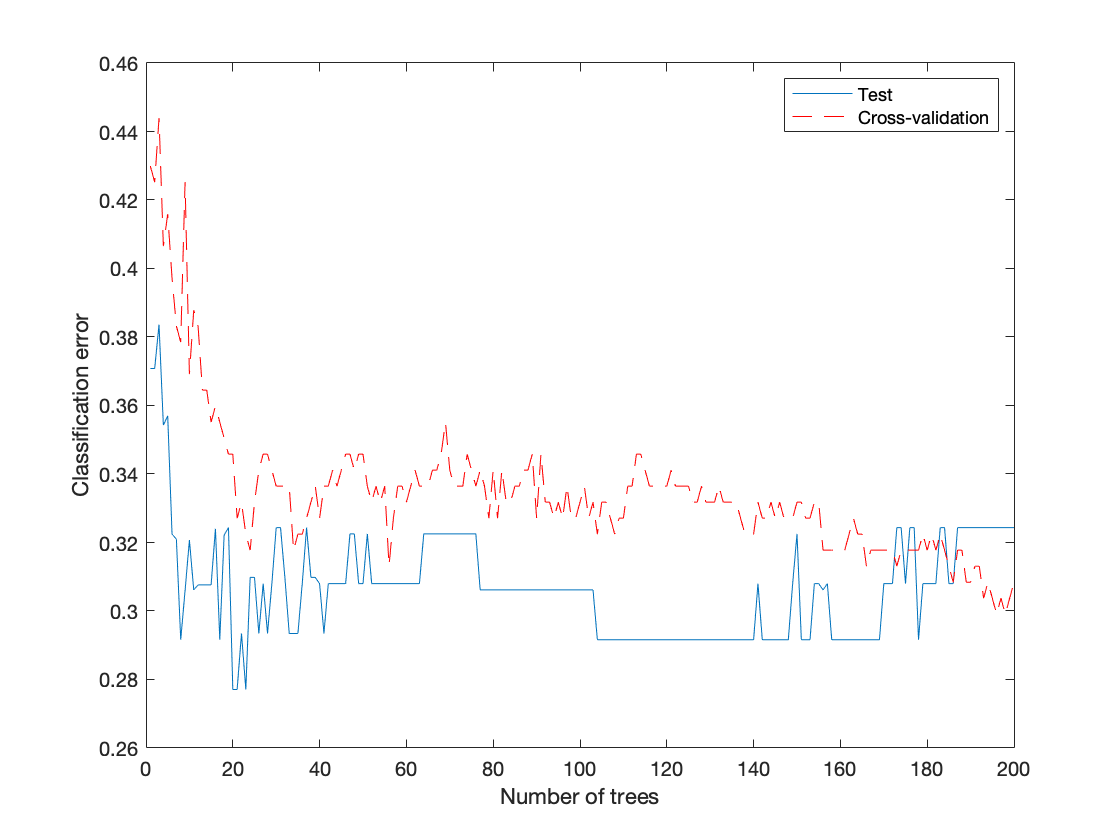

figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r--')
hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Location','NE')

Cross validating gives comparable estimates to those of the independent set.

#### iii. Out-of-Bag Estimates

Generate the loss curve for out-of-bag estimates, and plot it along with the other curves.

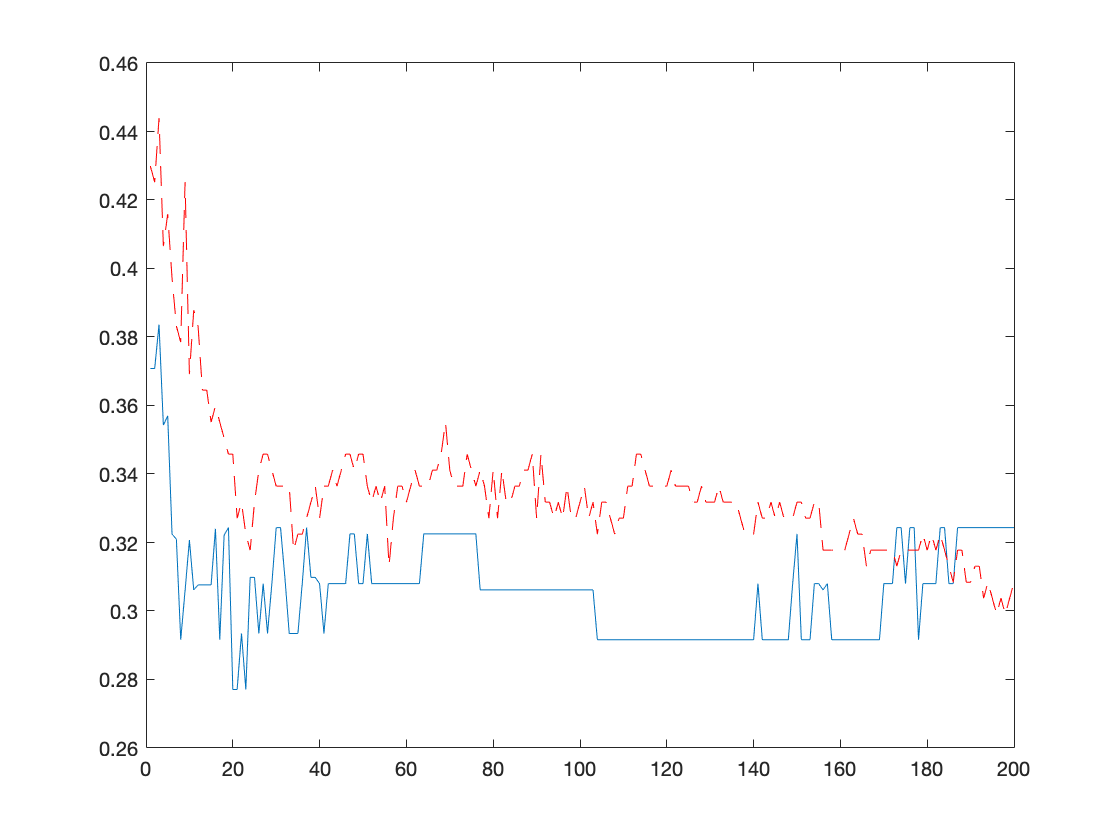

figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r--')

plot(oobLoss(rf_mdl,'mode','cumulative'),'k--')

Check for missing argument or incorrect argument data type in call to function 'oobLoss'.

hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Out of bag','Location','NE')

The out-of-bag estimates are again comparable to those of the other methods.

### Decision Trees

dt_mdl = fitctree(train_X, train_Y);

### K Nearest Neighbours

## **Validation**

## **Examine Fit and Update Use **

## **Fitted Model for Predictions**